## Problem 1

If in an interval $\left\lbrack a,b\right\rbrack$ a continuous function $f\left(x\right)$ changes sign, such that $f\left(a\right)f\left(b\right)<0$, then the bisection method provides a slow but reliable method that gaurantees convergence to a root of $f\left(x\right)$. On the other hand, Newton's method is usually very fast although its convergence depends on the choice of the initial iterate $x_0$. Let's create an algorithm that combines bisection and Newton's methods such that we can achieve fast and reliable convergence. The algorithm wil have the following structure: given an initial interval $\left\lbrack a_0 ,b_0 \right\rbrack$

- compute a first guess iterate using Newton's method

- If the new iterate is out of the interval use the bisection

- else update the interval $\left\lbrack a_n ,b_n \right\rbrack \;$using the Newton iterate

- repeat till the error is smaller than a given tolerance

After implementing the algorithm, apply it to find the root(s) of the function $2{\textrm{xe}}^{-15} -2e^{-15x} +1$. Check the number of bisection and Newton's steps and discuss the order in which the steps are taken. Finally, compare and comment on the convergence of this algorithm with respect to the bisection and Newton's method for the same initial parameters. 

clear all
close all
% 1
f0 = 0;
f = @(x) 2*x*exp(1).^(-15) - 2*exp(1).^(-15*x) + 1;
df = @(x) 2*exp(1).^(-15) - 2*-15*exp(1).^(15*x);


a0 = -5;
b0 = 10;
max_iter = 100;

t = 1:1:100;

x = 0 * t;
a = 0 * t;
b = 0 * t;

a(1) = a0;
b(1) = b0;


x0 = (a0 + b0) / 2;

x(1) = x0;

error = abs(f(x0));
tolerance = 1e-6;

i = 1;

bisection_steps = 0;
newton_steps = 0;

newton = 0 * t; % Newtons method is 1, bisection method is 0

while i < max_iter && error > tolerance

            midpoint = (a(i) + b(i))/2;

            x(i+1) = midpoint - f(midpoint)/df(midpoint);

    
        if x(i+1) < b(i) && x(i+1) > a(i)
            
            if f(midpoint) > 0
                a(i+1) = a(i);
                b(i+1) = x(i+1);
            else
                a(i+1) = x(i+1);
                b(i+1) = b(i);
            end



            newton(i) = 1;
            newton_steps = newton_steps + 1;
        else
            if f(midpoint) > 0
                a(i+1) = a(i);
                b(i+1) = midpoint;
            else
                a(i+1) = midpoint;
                b(i+1) = b(i);
            end

            newton(i) = 0;
            bisection_steps = bisection_steps + 1;

        end

        i = i + 1;
        error = abs(f(x(i)));


end

error

error = 9.0442e-07

x(i)

ans = 0.0462

f(x(i))

ans = -9.0442e-07

i

i = 24

bisection_steps

bisection_steps = 3

newton_steps

newton_steps = 20

newton

newton =      1     0     1     0     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


a

a =    -5.0000   -5.0000   -1.2500   -1.2500   -0.3125   -0.3125   -0.0794    0.0399    0.0399    0.0399    0.0399    0.0454    0.0454    0.0454    0.0460    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


b

b =    10.0000    2.5000    2.5000    0.6250    0.6250    0.1537    0.1537    0.1537    0.0926    0.0631    0.0503    0.0503    0.0475    0.0464    0.0464    0.0464    0.0463    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462    0.0462         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


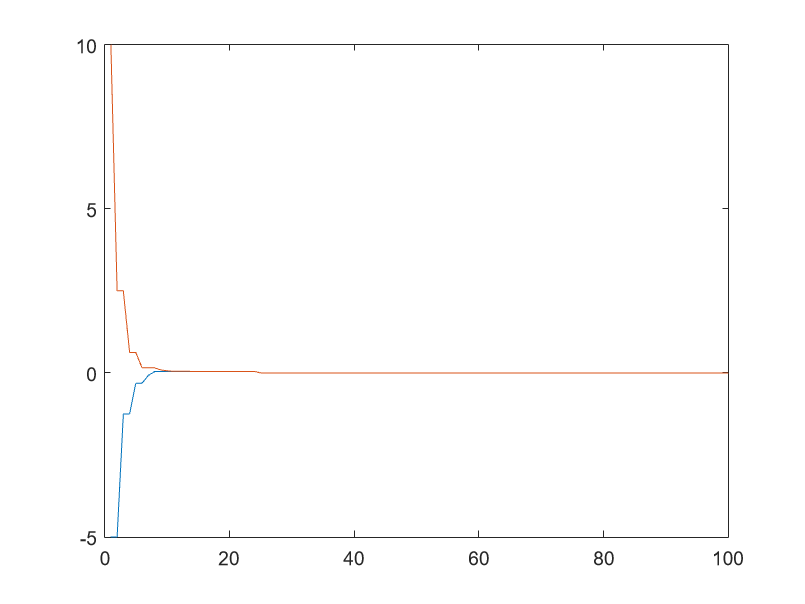

plot(t,a,t,b)


f1 = @(y) 2*y*exp(1).^(-15) - 2*exp(1).^(-15*y) + 1;
df1 = @(y) 2*exp(1).^(-15) - 2*-15*exp(1).^(15*y);

y = 0.01;
error2 = abs(f1(y));

g = 0;

while error2 > tolerance && g < 100

    y = y - f1(y)/df1(y);
    y;

    error2 = abs(f1(y));
    error2;
    g = g + 1;
end
g

g = 43

This method includes a couple of bisection steps towards the start. Intuitively this makes sense: the initial guess must be fairly close for the newton's method part of the algorithm to converge. Note that the method only uses bisection steps because the interval was changed to not center at 0. Initially it was [-10,10] and it did not include any bisection steps because it was already very close to the solution.. This method converges in fewer steps than newton's method for the chosen function. I'm unsure if it would converge in fewer steps than newton's method for all functions or for the same function with a different interval. This method converges in fewer steps than a pure bisection method.